# Connect Poses Using UAV Dubins Connection Path

This example shows how to calculate a UAV Dubins path segment and connect poses using the [`uavDubinsConnection`](docid:uav_ref#object_uavdubinsconnection) object.

Create a `uavDubinsConnection` object. 

connectionObj = uavDubinsConnection;
connectionObj.AirSpeed = 1;
% connectionObj.MinTurningRadius = 40;
connectionObj.MaxRollAngle = atan(1/(40*9.80));
fprintf('Minimum turning radius is %f', connectionObj.MinTurningRadius);

Minimum turning radius is 40.000000

% connectionObj.MaxRollAngle = 0.8;
% connectionObj.FlightPathAngleLimit = [-1.47 1.47];

Define start and goal poses as [`x`, `y`, `z`, `headingAngle`] vectors.

% Long 1
% startPose = [200 500 200 180*pi/180]; % [meters, meters, meters, radians]
% goalPose = [500 350 100 0*pi/180];

% Long 2
% startPose = [100, -400, 100, 30*pi/180];
% goalPose = [500, -700, 0, 150*pi/180];

% Long 3
% startPose = [-200, 200, 250, 240*pi/180];
% goalPose = [ 500, 800,   0, 45*pi/180];

% Long 4
% startPose = [-300, 1200, 350, 160*pi/180];
% goalPose  = [1000,  200,   0, 30*pi/180];

% Long 5
% startPose = [-500, -300, 600, 150*pi/180];
% goalPose  = [1200,  900, 100, 300*pi/180];

% Short 1
% startPose = [120,  -30, 250, 100*pi/180];
% goalPose  = [220,  150, 100, 300*pi/180];

% Short 2
% startPose = [380, 230, 200, 30*pi/180];
% goalPose  = [280, 150,  30, 200*pi/180];

% Short 3
% startPose = [-80, 10, 250, 20*pi/180];
% goalPose  = [ 50, 70,   0, 240*pi/180];

% Short 4
% startPose = [400, -250, 600, 350*pi/180];
% goalPose  = [600, -150, 300, 150*pi/180];

% Short 5
% startPose = [-200, -200, 450, 340*pi/180];
% goalPose  = [-300,  -80, 100, 100*pi/180];

% Additional 1
% startPose = [120, 40, 20, 90*pi/180];
% goalPose  = [300, 40, 15, -90*pi/180];

% Additional 2
% startPose = [120,  40, 20, 90*pi/180];
% goalPose  = [130, 120, 41, 85*pi/180];

% Inside pitch
% startPose = [0,  0,  0, 30*pi/180];
% goalPose  = [5, 10, 15, 190*pi/180];

% Inside yaw
startPose = [ 0,   0,  0, -30*pi/180];
goalPose  = [ 0, -30,  5, 190*pi/180];

Calculate a valid path segment and connect the poses. Returns a path segment object with the lowest path cost.

[pathSegObj,pathCosts] = connect(connectionObj,startPose,goalPose);
pathSegObj

pathSegObj = 1×1 cell array
    {1×1 uavDubinsPathSegment}


Show the generated path.

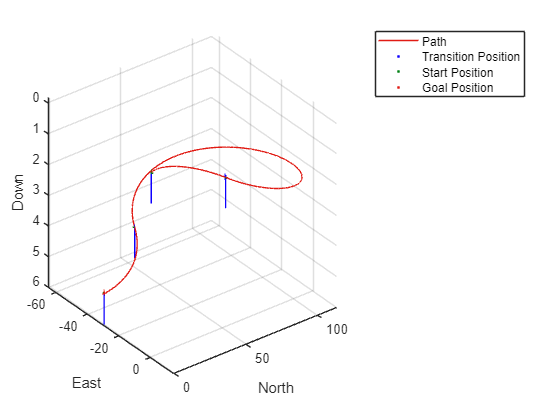

ax = show(pathSegObj{1});

children = ax.Children;

% Find the line object for the path (it's the red line)
% Loop through to find it, or just inspect:
for i = 1:length(children)
    disp(i)
    disp(class(children(i)))
end

     1



matlab.graphics.primitive.Group


     2



matlab.graphics.chart.primitive.Line


     3



matlab.graphics.primitive.Group


     4



matlab.graphics.chart.primitive.Line


     5



matlab.graphics.primitive.Group


     6



matlab.graphics.chart.primitive.Line


     7



matlab.graphics.chart.primitive.Line


lines = findobj(ax, 'Type', 'line');

% Find the line with the most data points (that's the path)
numPoints = arrayfun(@(l) length(l.XData), lines);
[~, idx] = max(numPoints);
pathLine = lines(idx);

x = pathLine.XData;
y = pathLine.YData;
z = pathLine.ZData;

% Combine into Nx3 matrix
coords = [x(:), y(:), z(:)];
coords

coords =          0         0         0
    0.0433   -0.0250    0.0009
    0.0867   -0.0499    0.0017
    0.1300   -0.0747    0.0026
    0.1734   -0.0996    0.0034
    0.2169   -0.1243    0.0043
    0.2603   -0.1490    0.0052
    0.3038   -0.1736    0.0060
    0.3474   -0.1982    0.0069
    0.3909   -0.2228    0.0077


Display the motion type and the path cost of the generated path.

fprintf('Motion Type: %s\nPath Cost: %f\n',strjoin(pathSegObj{1}.MotionTypes),pathCosts);

Motion Type: R L R N
Path Cost: 290.625140


*Copyright 2020 The MathWorks, Inc.*